# BEV System Model - Simulation Case

modelName = "BEV_system_model";
load_system(modelName)
BEV_useComponents_Basic

Use Basic models for all components.


VehSpdRef_loadCase_WLTP( ...
  ModelName = modelName, ...
  TargetSubsystemPath = ...
    "/Controller & Environment" + ...
    "/Vehicle speed reference" )

Setting up simulation...
Simulation case: WLTP Class 3 drive cycle using Drive Cycle Source block
Setting simulation stop time to 1800 sec.
Selecting simulation case 4.


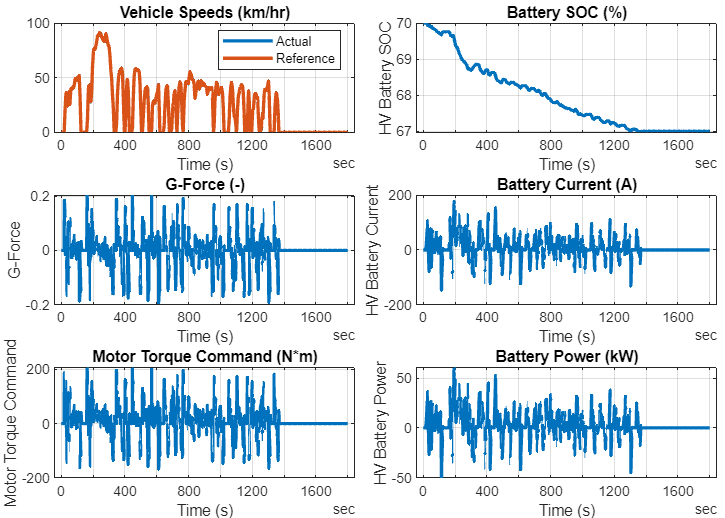

simOut = sim(modelName);
simData = extractTimetable(simOut.logsout);
fig = BEV_plotResultsCompact( SimData = simData, PlotTemperature = false );

*Copyright 2023-2024 The MathWorks, Inc.*